# 案例：用 Matlab 绘制高质量的论文插图 3

## 自定义颜色图

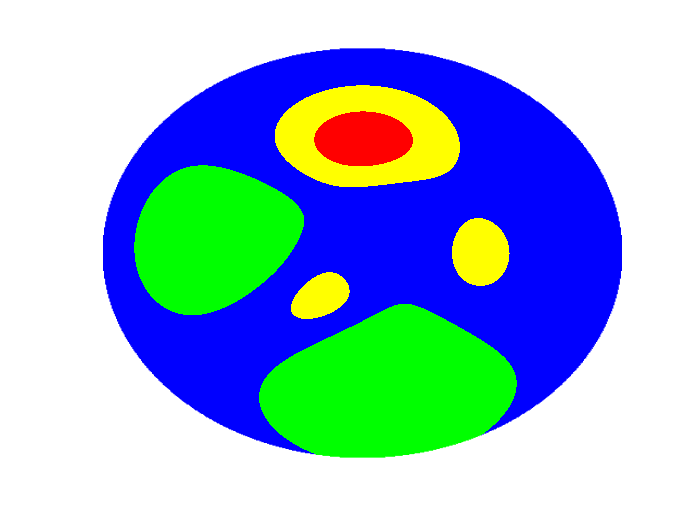

N = 500;
z = peaks(N);
% 选择 ROI 以外的不显示
for i = 1:N
    for j = 1:N
        if sqrt((i - N/2)*(i - N/2) + (j - N/2)*(j - N/2)) > 240
            z(i, j) = nan;
        end
    end
end
% 自定义颜色 大概就是给特定范围值指定颜色
N = 14 * 5;
crange = linspace(-6, 8, N);
cmap = zeros(N, 3);
for i = 1:N
    if crange(i) <= 0
        cmap(i, :) = [0, 1, 0];
    elseif crange(i) <= 3
        cmap(i, :) = [0, 0, 1];
    elseif crange(i) <= 6
        cmap(i, :) = [1, 1, 0];
    else
        cmap(i, :) = [1, 0, 0];
    end
end
figure;
surf(z)
colormap(cmap);
% 去网格
shading interp
% 视角
view(0, 90);
% 去坐标轴
axis off

## gif 动态图

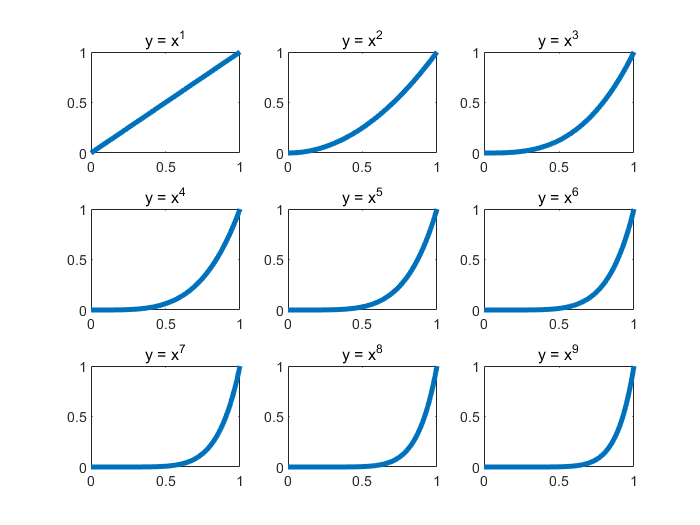

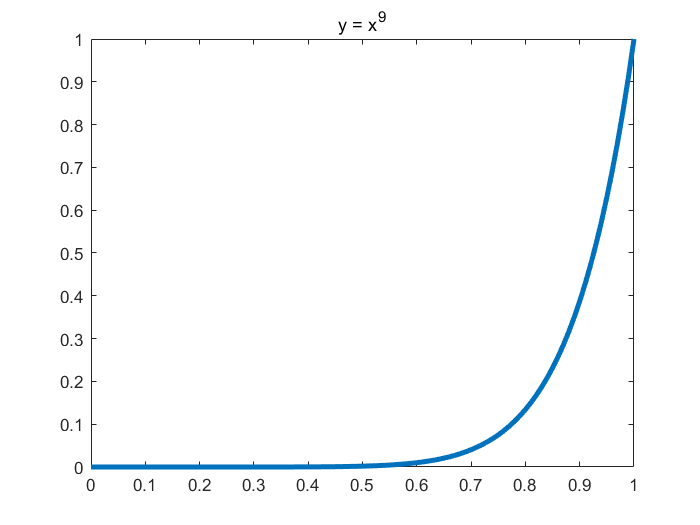

clear; clc;
x = 0:0.01:1;
n = 1:9;
len = length(n);
im = cell(1, len);
% 单独显示每个图
figure;
for idx = 1:len
    subplot(3, 3, idx)
    plot(x, x.^idx, 'LineWidth',3)
    title(['y = x^', num2str(idx)])
end
% 获取绘制对象
fig = figure(1);
for idx = 1:len
    y = x.^idx;
    plot(x, y, 'LineWidth', 3)
    title(['y = x^', num2str(n(idx))])
%     drawnow
%     pause(0.1);
    frame = getframe(fig);
    im{idx} = frame2im(frame);
end

% 输出文件名
% filename = 'testAnimated.gif'; 
% for idx = 1:len
%     % 制作gif文件，图像必须是index索引图像
%     [A, map] = rgb2ind(im{idx}, 256);
%     if idx == 1
%         imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
%     else
%         imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
%     end
% end

## 方程曲线图

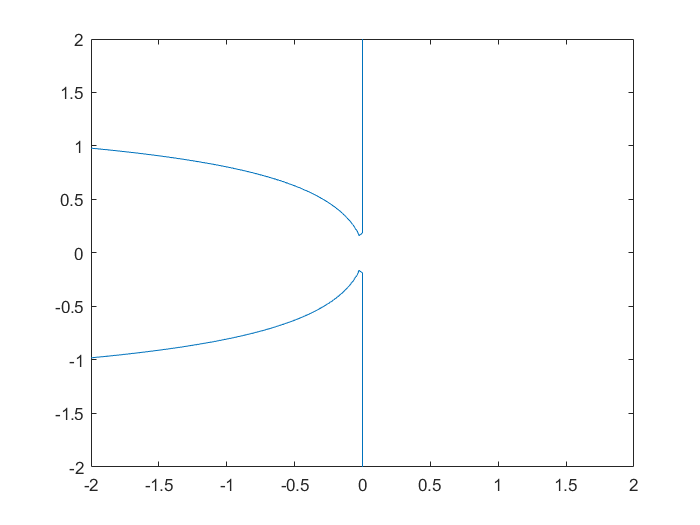

% 二元方程  x^2*cos(y) + x*sinh(y^2) = 0
xy = linspace(-2, 2, 4);
[x, y] = meshgrid(xy);
f = @(x, y) x.^2.*cos(y) + x.*sinh(y.^2);
figure
fimplicit(f, [-2, 2]);

## 极坐标图

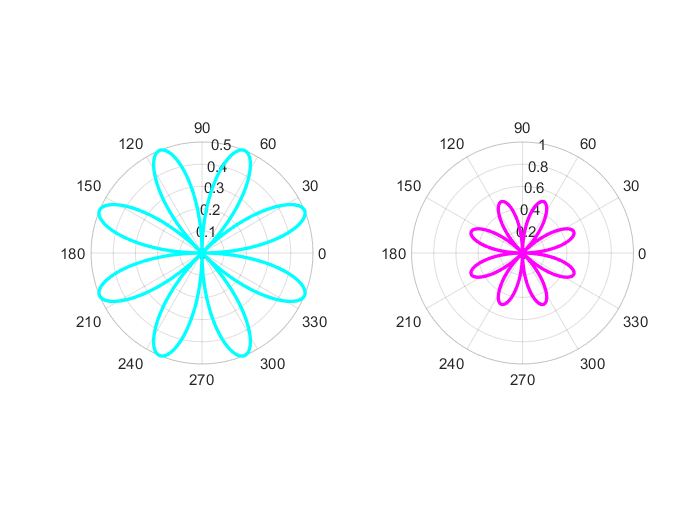

figure;
theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(2*theta);
tiledlayout(1, 2);
nexttile;
polarplot(theta, rho, 'c', 'LineWidth', 2);
nexttile;
rMax = 2*max(rho);
% 这个看不到线，因为只有一个重复的点
polarplot([0, 2*pi], [rMax, rMax]);    
hold on
polarplot(theta, rho, 'm', 'LineWidth', 2);
hold off